### **Иван Шаламов, 551 группа. Лабораторная работа № 5.1, 2020.**

clc;
close all;
clear;
opengl software;

### **Практическая часть.**

disp('Рассматривается линейное уравнение теплопроводности.');

Рассматривается линейное уравнение теплопроводности.


Ввод начальных параметров.

TextSize = 15;

MyAns1 = inputdlg({'Transfer factor: ', 'Number of cells: ', ...
    'Size of the computational domain: ', 'Left boundary value: ', ...
    'Right boundary value: ', 'Relative position of the start value break point: '}, ...
    'Initial values', [1 50], {'1', '301', '1', '0.1', '0.8', '0.5'});

a = str2double(MyAns1{1}); % коэффициент переноса
N = str2double(MyAns1{2}); % количество узлов
x_scale = str2double(MyAns1{3}); % размер расчетной области
LBV = str2double(MyAns1{4}); % левое граничное значение
RBV = str2double(MyAns1{5}); % правое граничное значение
BreakPoint = str2double(MyAns1{6}); % точка разрыва

dh = x_scale / (N - 1); % шаг по пространству
dt_allowed = dh^2 / (2 * a); % верхняя граница шага по времени

MyAns2 = inputdlg(['Allowed time step dt <= ', num2str(dt_allowed), ...
        '. Input time step: '], 'Time step', [1 50], {num2str(dt_allowed)}); 
dt = str2double(MyAns2{1}); % шаг по времени
sp = 10; % остановочное число

Введение сетки и векторов подстановок.

x = 0:dh:x_scale; % сетка по x

LeftPoints = find(x <= BreakPoint*x_scale); % точки слева от точки разрыва
RightPoints = find(x > BreakPoint*x_scale); % точки справа от точки разрыва

Решение явной схемой. Условие устойчивости: r = a * t / h^2 <= 0.5 ("сеточное" число Фурье). Порядок аппроксимации в общем случае: O(t, h^2).

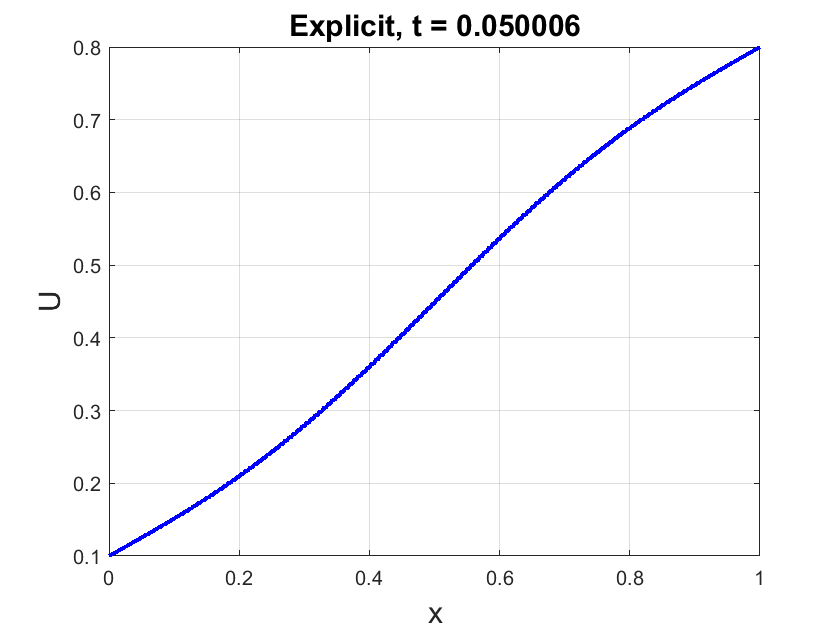

Uexpl = Explicit(x, a, N, LBV, RBV, dh, dt, ...
    LeftPoints, RightPoints, sp, TextSize);

### **Исследовательская часть.**

Решение трехслойной схемой Дюфорта - Франкела (схемой "чехарда"). Абсолютная устойчивость при t / h -> 0. Порядок аппроксимации: O(t^2, h^2) + O(t^2 / h^2).

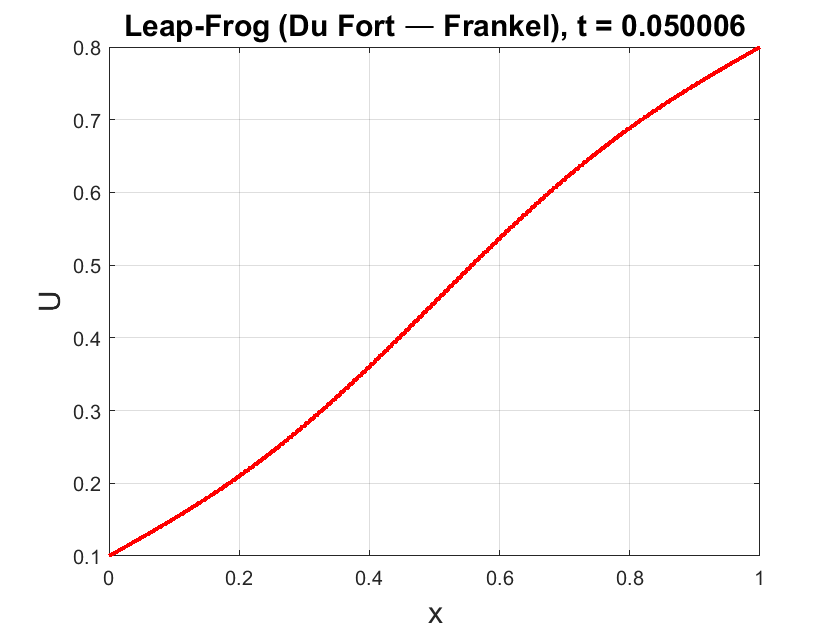

Uleap = LeapFrogDF(x, a, N, LBV, RBV, dh, dt, ...
    LeftPoints, RightPoints, sp, TextSize);

Решение двухслойной схемой Аллена — Чена. Абсолютная устойчивость. Порядок аппроксимации: O(t, h^2) + O(t / h^2).

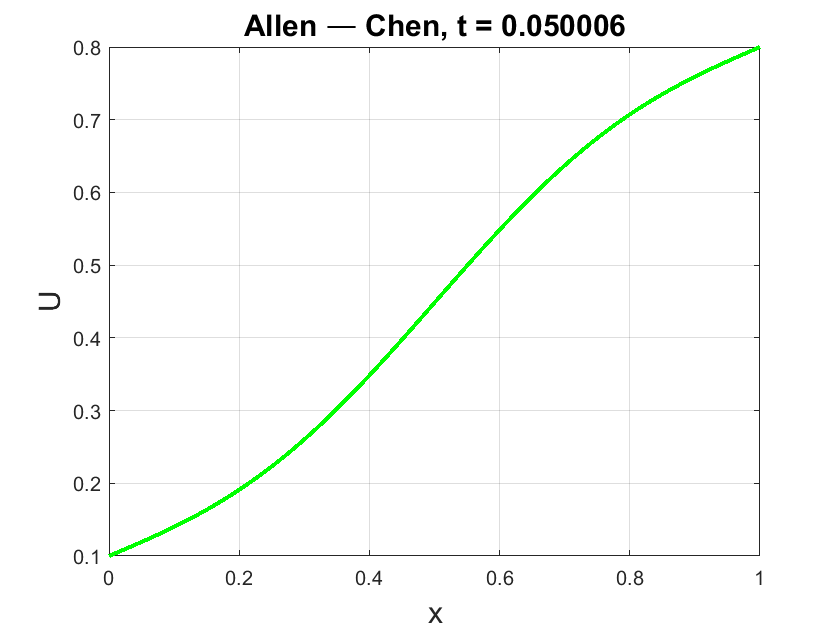

Uac = AllenChen(x, a, N, LBV, RBV, dh, dt, ...
    LeftPoints, RightPoints, sp, TextSize);

Сравнение результатов различных схем.

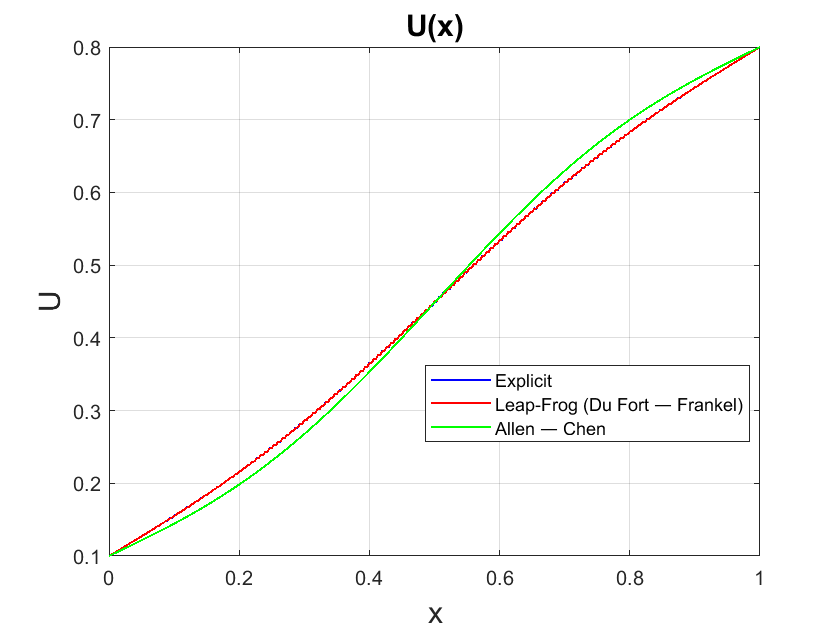

plot(x, Uexpl, '-b', x, Uleap, '-r', x, Uac, '-g', 'LineWidth', 1);
grid on;
title('U(x)', 'FontSize', TextSize);
xlabel('x', 'FontSize', TextSize);
ylabel('U', 'FontSize', TextSize);
legend({'Explicit', 'Leap-Frog (Du Fort — Frankel)', 'Allen — Chen'}, 'Location', 'best');

Изменение параметров, их влияние на схемы. При нарушении условия на шаг по времени для явной схемы — решение "рассыпается".

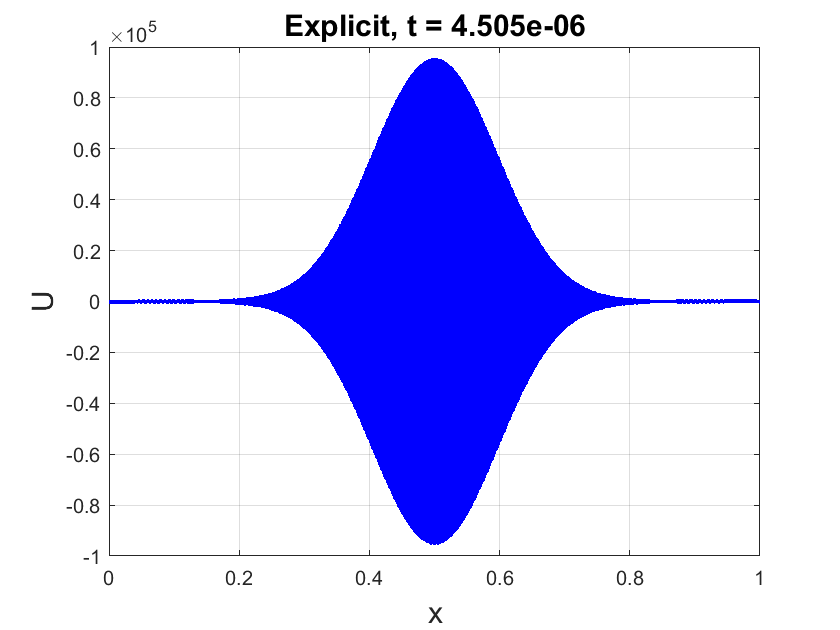

a = 1000; % коэффициент переноса
N = 1001; % количество узлов
dh = x_scale / (N - 1); % шаг по пространству
dt_allowed = dh^2 / (2 * a); % верхняя граница шага по времени
dt = dt_allowed * 1.001; % шаг по времени
x = 0:dh:x_scale; % сетка по x
LeftPoints = find(x <= BreakPoint*x_scale); % точки слева от точки разрыва
RightPoints = find(x > BreakPoint*x_scale); % точки справа от точки разрыва

Uexpl = Explicit(x, a, N, LBV, RBV, dh, dt, ...
    LeftPoints, RightPoints, sp, TextSize);

Схема Дюфорта — Франкела лучше приближает решение, чем схема Аллена — Чена, так как имеет более высокий порядок аппроксимации.

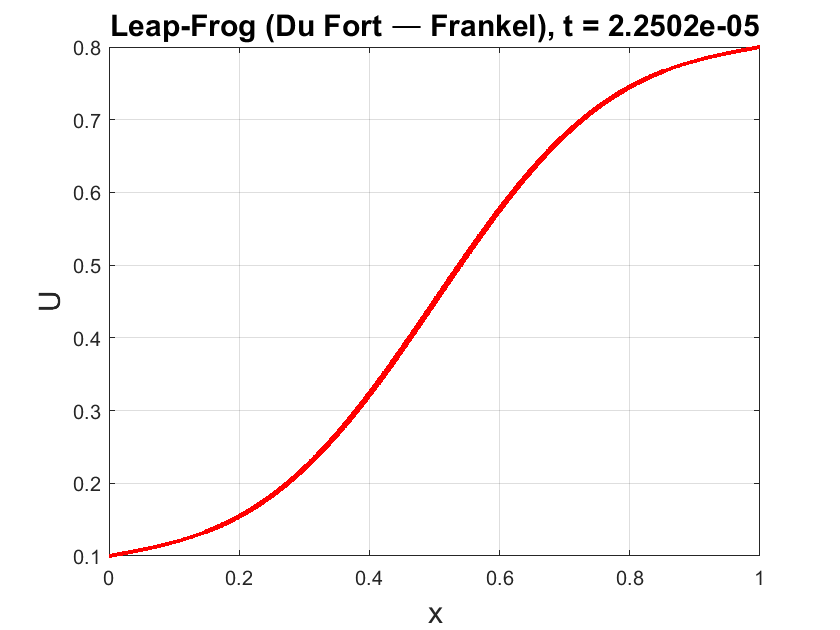

dt = dt_allowed * 5;

Uleap = LeapFrogDF(x, a, N, LBV, RBV, dh, dt, ...
    LeftPoints, RightPoints, sp, TextSize);

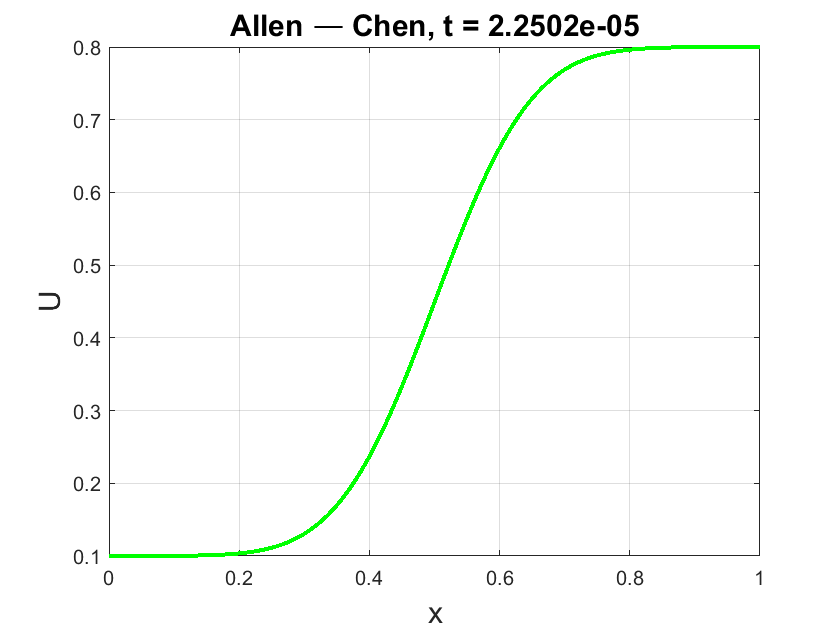

Uac = AllenChen(x, a, N, LBV, RBV, dh, dt, ...
    LeftPoints, RightPoints, sp, TextSize);

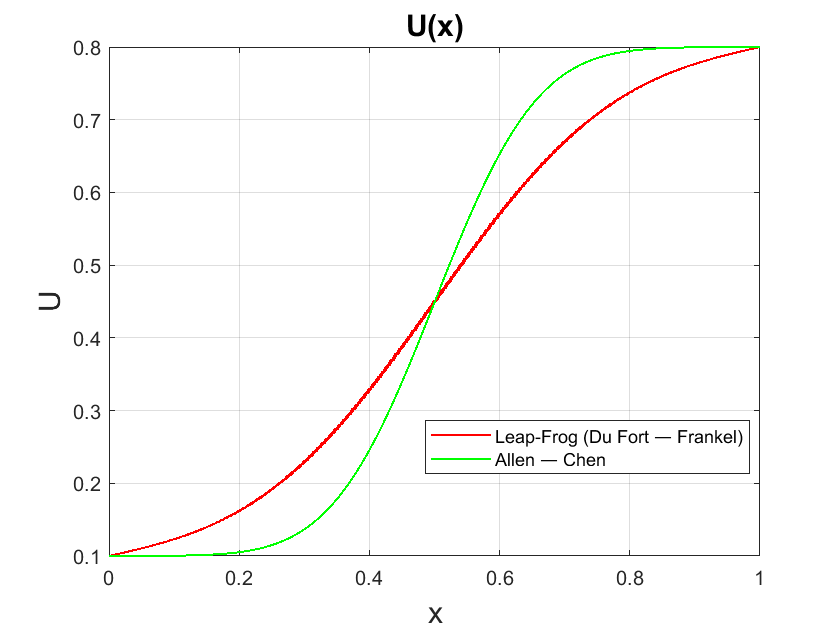

plot(x, Uleap, '-r', x, Uac, '-g', 'LineWidth', 1);
grid on;
title('U(x)', 'FontSize', TextSize);
xlabel('x', 'FontSize', TextSize);
ylabel('U', 'FontSize', TextSize);
legend({'Leap-Frog (Du Fort — Frankel)', 'Allen — Chen'}, 'Location', 'best');

### **Использованные функции.**

Явная схема.

function Uold = Explicit(x, a, N, LBV, RBV, dh, dt, ...
    LeftPoints, RightPoints, sp, TextSize)
    
    t = 0; % переменная времени
    plot_interval = 1000; % интервал вывода графиков
    plot_time = 1; % итерационный индекс графиков
    step = 0; % итерационный индекс цикла
    stop = sp * plot_interval; % остановочное значение
    
    tmp1 = dt * a / dh^2; % вспомогательная переменная счета
    tmp2 = 1 - 2 * tmp1; % вспомогательная переменная счета
    
    % Начальные значения:
    Uold = zeros(1, N);
    Unew = Uold;
    
    Uold(LeftPoints) = LBV;
    Uold(RightPoints) = RBV;
    
    while 1
        
        step = step + 1;
        t = t + dt;
        
        % График изменения решения:
        if step == plot_time
            
            plot_time = plot_time + plot_interval;
            plot(x, Uold, 'b', 'LineWidth', 2);
            grid on;
            title(['Explicit, t = ', num2str(t)], 'FontSize', TextSize);
            xlabel('x', 'FontSize', TextSize);
            ylabel('U', 'FontSize', TextSize);
            pause(0.5);
            
        end
        
        % Явная схема:
        Unew(2:N-1) = tmp2 * Uold(2:N-1) + ...
            tmp1 * (Uold(1:N-2) + Uold(3:N));
        
        % Граничные условия:
        Unew(1) = LBV;
        Unew(N) = RBV;
        
        if step >= stop
            
            break;
            
        end
        
        Uold = Unew;
        
    end
    
end

Трехслойная схема Дюфорта — Франкела (схема "чехарда").

function Uold2 = LeapFrogDF(x, a, N, LBV, RBV, dh, dt, ...
    LeftPoints, RightPoints, sp, TextSize)
    
    t = 0; % переменная времени
    plot_interval = 1000; % интервал вывода графиков
    plot_time = 1; % итерационный индекс графиков
    step = 0; % итерационный индекс цикла
    stop = sp * plot_interval; % остановочное значение
    
    tmp1 = 2 * dt * a / dh^2; % вспомогательная переменная счета
    tmp2 = 1 + tmp1; % вспомогательная переменная счета
    
    % Начальные значения:
    Uold1 = zeros(1, N);
    Uold2 = Uold1;
    Unew = Uold1;
    
    Uold1(LeftPoints) = LBV;
    Uold1(RightPoints) = RBV;
    Uold2(LeftPoints) = LBV;
    Uold2(RightPoints) = RBV;
    
    while 1
        
        step = step + 1;
        t = t + dt;
        
        % График изменения решения:
        if step == plot_time
            
            plot_time = plot_time + plot_interval;
            plot(x, Uold2, 'r', 'LineWidth', 2);
            grid on;
            title(['Leap-Frog (Du Fort — Frankel), t = ', num2str(t)], ...
                'FontSize', TextSize);
            xlabel('x', 'FontSize', TextSize);
            ylabel('U', 'FontSize', TextSize);
            pause(0.5);
            
        end
        
        % Трехслойная схема Дюфорта — Франкела (схема "чехарда"):
        Unew(2:N-1) = tmp1 / tmp2 * (Uold2(1:N-2) - Uold1(2:N-1) + ...
            Uold2(3:N)) + Uold1(2:N-1) / tmp2;
        
        % Граничные условия:
        Unew(1) = LBV;
        Unew(N) = RBV;
        
        if step >= stop
            
            break;
            
        end
        
        Uold1 = Uold2;
        Uold2 = Unew;
        
    end
    
end

Схема Аллена — Чена (двухшаговая).

function Uold = AllenChen(x, a, N, LBV, RBV, dh, dt, ...
    LeftPoints, RightPoints, sp, TextSize)
    
    t = 0; % переменная времени
    plot_interval = 1000; % интервал вывода графиков
    plot_time = 1; % итерационный индекс графиков
    step = 0; % итерационный индекс цикла
    stop = sp * plot_interval; % остановочное значение
    
    tmp1 = dt * a / dh^2; % вспомогательная переменная счета
    tmp2 = 1 + 2 * tmp1; % вспомогательная переменная счета
    
    % Начальные значения:
    Uold = zeros(1, N);
    Upred = Uold;
    Unew = Uold;
    
    Uold(LeftPoints) = LBV;
    Uold(RightPoints) = RBV;
    Upred(1) = LBV;
    Upred(N) = RBV;
    
    while 1
        
        step = step + 1;
        t = t + dt;
        
        % График изменения решения:
        if step == plot_time
            
            plot_time = plot_time + plot_interval;
            plot(x, Uold, '-g', 'LineWidth', 2);
            grid on;
            title(['Allen — Chen, t = ', num2str(t)], 'FontSize', TextSize);
            xlabel('x', 'FontSize', TextSize);
            ylabel('U', 'FontSize', TextSize);
            pause(0.5);
            
        end
        
        % Схема Аллена — Чена (двухшаговая):
        
        % Первый шаг - предиктор:
        Upred(2:N-1) = Uold(2:N-1) / tmp2 + tmp1 / tmp2 * ...
            (Uold(1:N-2) + Uold(3:N));
        
        % Второй шаг - корректор:
        Unew(2:N-1) = Uold(2:N-1) / tmp2 + tmp1 / tmp2 * ...
            (Upred(1:N-2) + Upred(3:N));
        
        % Граничные условия:
        Unew(1) = LBV;
        Unew(N) = RBV;
        
        if step >= stop
            
            break;
            
        end
        
        Uold = Unew;
        
    end
    
end